## A face image

Force the scene to have an odd number of rows and columns.  Also 10 deg, which is more typical of viewing distance and sampling density.

ieInit;

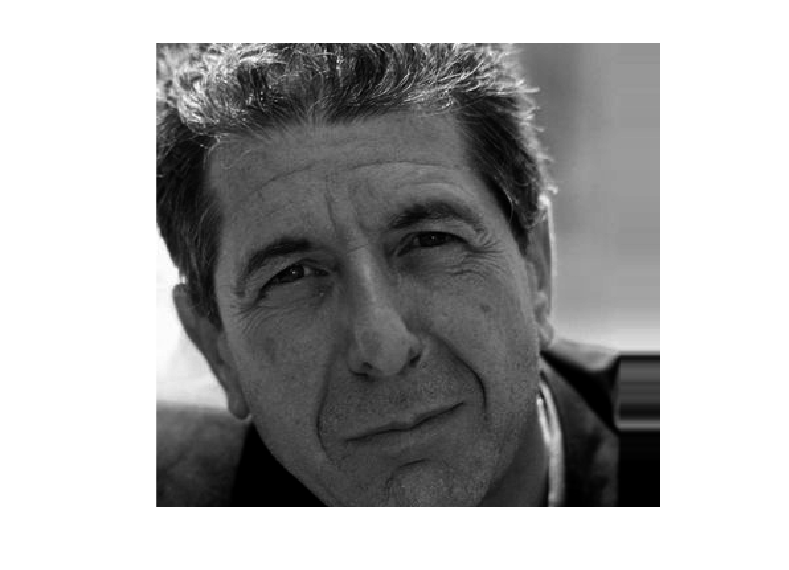

scene = sceneFromFile('faceMale.jpg','rgb',[],displayCreate);
scene = sceneSet(scene,'fov',10);
imSize = sceneGet(scene,'size');
newSize = round(imSize/2)*2 - 1;
scene = sceneCrop(scene,[1 1 newSize(1)-1 newSize(2)-1]);

% Spatial frequency support.
fx = sceneGet(scene,'f support x'); fullFx = [-1*fliplr(fx), fx];
fy = sceneGet(scene,'f support y'); fullFy = [-1*fliplr(fy), fy];

% Space support.
x = sceneGet(scene,'spatial support x','deg');
y = sceneGet(scene,'spatial support y','deg');

% sceneWindow(scene);
img = sceneGet(scene, 'luminance');
ieFigure; imagesc(img); colormap("gray"); axis image; axis tight; axis off;

## Display the loaded face image

Shows the images and corresponding Fourier Transform amplitude representations in the top and bottom rows.

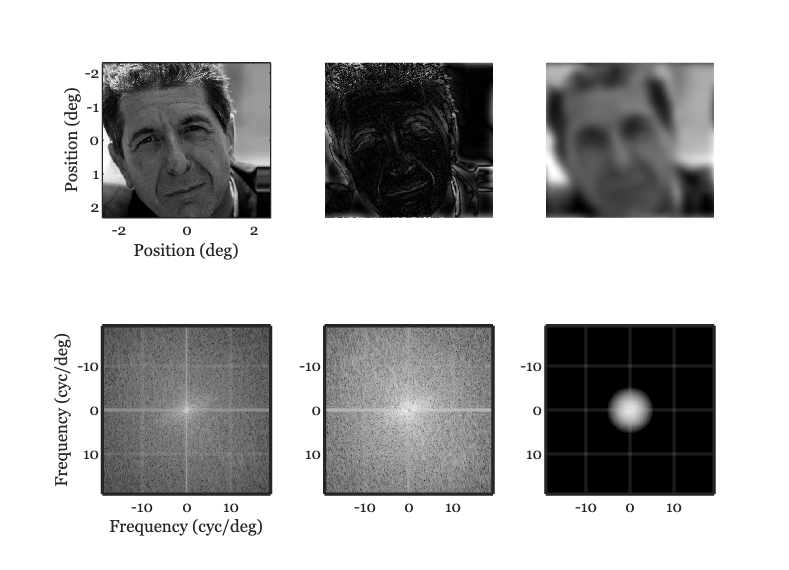

ieFigure;
subplot(2,3,1);

imagesc(x,y,img); axis image
xlabel('Position (deg)'); ylabel('Position (deg)');

% Now the log of the FFT amplitude.
subplot(2,3,4);
imgF = fft2(img);
imagesc(fullFx,fullFy,log10(abs(fftshift(imgF)))); 
axis equal; axis image; colormap(gray);
set(gca, 'Color', 'k'); % Set background color to black
grid on; % Turn on the grid
ax = gca; % Get current axes
ax.GridColor = [0.7 0.7 0.7]; % Set grid color to dark gray
ax.GridLineStyle = '-'; % Set grid line style
ax.LineWidth = 3; % Set grid line thickness
xlabel('Frequency (cyc/deg)');
ylabel('Frequency (cyc/deg)');

%{
% Show that we can invert the FFT to reconstruct the image
nexttile
imagesc(x,y,fliplr(abs(fft2(imgF)))); % Corrected to display the magnitude of the Fourier transform
axis equal; axis xy; axis off
title('Reconstructed image.');
%}

%% Create a Gaussian kernel 
% It is constructed to reduce low frequency terms 
% mesh(FX,FY,lowFreqReduction);

[FX, FY] = meshgrid(fullFx(1:(end-1)), fullFy(1:(end-1)));

% Standard deviation for the Gaussian
sigma = 0.6;   
lowFreqReduction = 1 - exp(-(FX.^2 + FY.^2) / (2 * sigma^2));

%% Apply the Gaussian kernel to imgF, worrying about the fftshift
subplot(2,3,2);
imgF_reduced = fftshift(imgF) .* (lowFreqReduction);
imagesc(x,y,fliplr(abs(fft2(fftshift(imgF_reduced))))); % Corrected to display the magnitude of the Fourier transform
axis equal; axis xy; axis off

% Show the scaled FFT
subplot(2,3,5);
imagesc(fullFx,fullFy,log10(abs(imgF_reduced))); 
axis equal; axis image; colormap(gray);
set(gca, 'Color', 'k'); % Set background color to black
grid on; % Turn on the grid
ax = gca; % Get current axes
ax.GridColor = [0.7 0.7 0.7]; % Set grid color to dark gray
ax.GridLineStyle = '-'; % Set grid line style
ax.LineWidth = 3; % Set grid line thickness

% Flip the reduction
subplot(2,3,3);
imgF_reduced = fftshift(imgF) .* (1-lowFreqReduction);
imagesc(x,y,fliplr(abs(fft2(fftshift(imgF_reduced))))); % Corrected to display the magnitude of the Fourier transform
axis equal; axis xy; axis off

% Show the transform itself
subplot(2,3,6);
imagesc(fullFx,fullFy,log10(abs(imgF_reduced))); 
axis equal; axis image; colormap(gray);
set(gca, 'Color', 'k'); % Set background color to black
grid on; % Turn on the grid
ax = gca; % Get current axes
ax.GridColor = [0.7 0.7 0.7]; % Set grid color to dark gray
ax.GridLineStyle = '-'; % Set grid line style
ax.LineWidth = 3; % Set grid line thickness


%{
theDir = fullfile(fiseRootPath,'chapters','images','optics');
exportgraphics(gcf,fullfile(theDir,'otf2dFace.png'));
%}
